tref = 0:0.01:63;
xref = sin(tref);

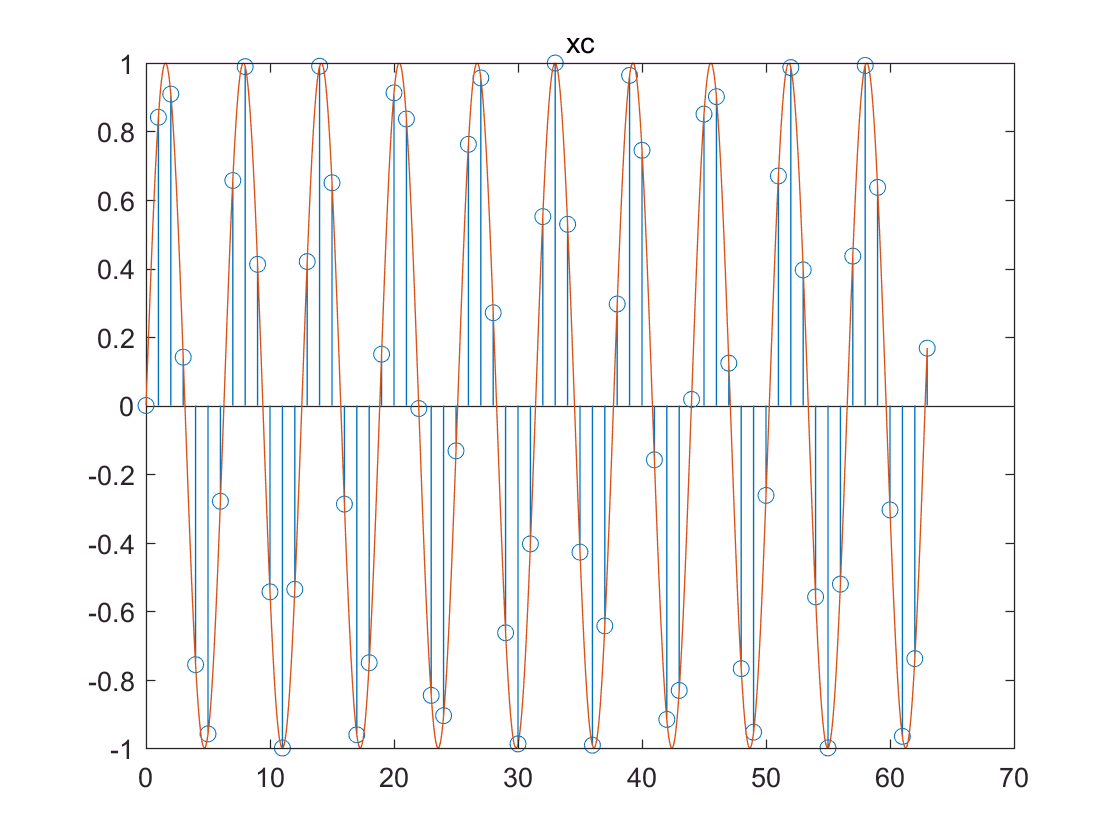

t=0:63;
xc = sin(t);%w = 1 < pi无失真采样
stem(t,xc)
title('xc')
hold on
plot(tref,xref)
hold off

# 降采样


$$x\left\lbrack n\right\rbrack =x_c \left(2{\mathrm{nT}}_s \right)\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ },n=0,1,\ldotp \ldotp \ldotp ,\left(\frac{N}{2}-1\right)$$


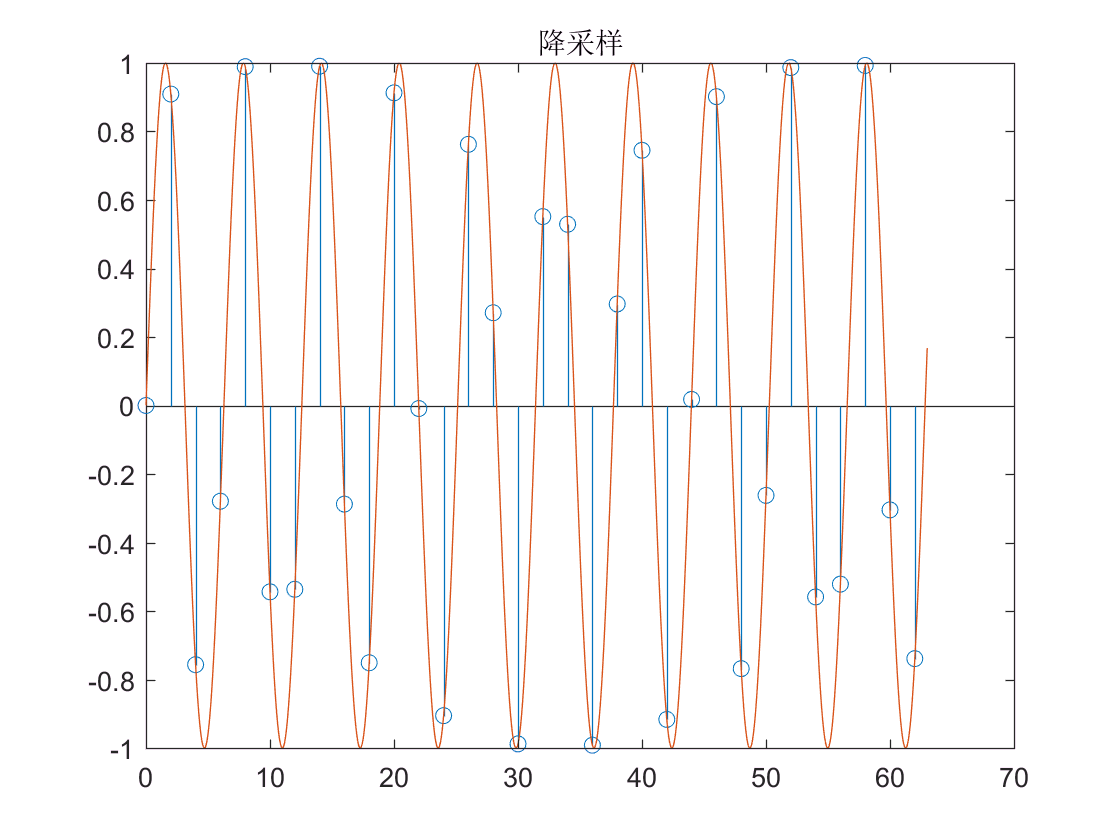

t1 = 0:31;
x1 = sin(2*t1);%w = 2 < pi无失真
stem(t1*2,x1)
title('降采样')
hold on
plot(tref,xref)
hold off

## 降采样真正的离散时域

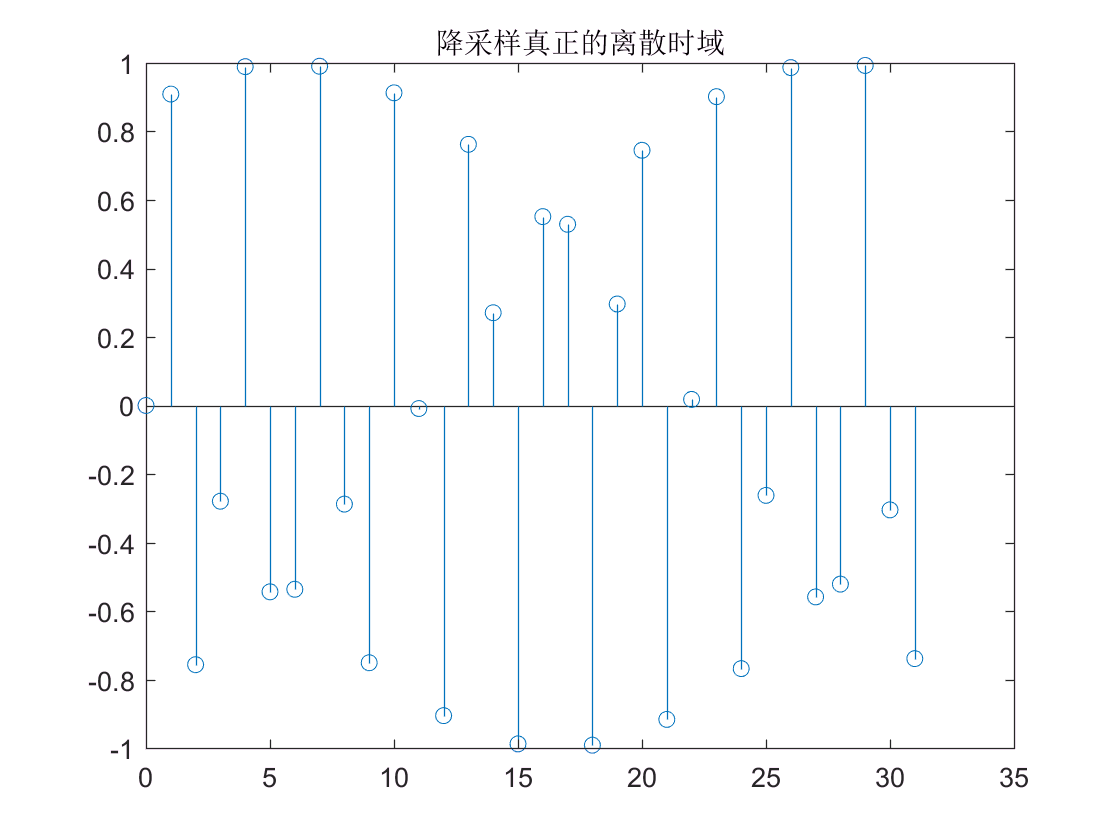

stem(t1,x1)
title('降采样真正的离散时域')

# 增采样

## 经过内插的增采样


$$x\left\lbrack n\right\rbrack =x_c \left(n\frac{T_s }{2}\right)\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ },n=0,1,\ldotp \ldotp \ldotp ,\left(2N-1\right)$$


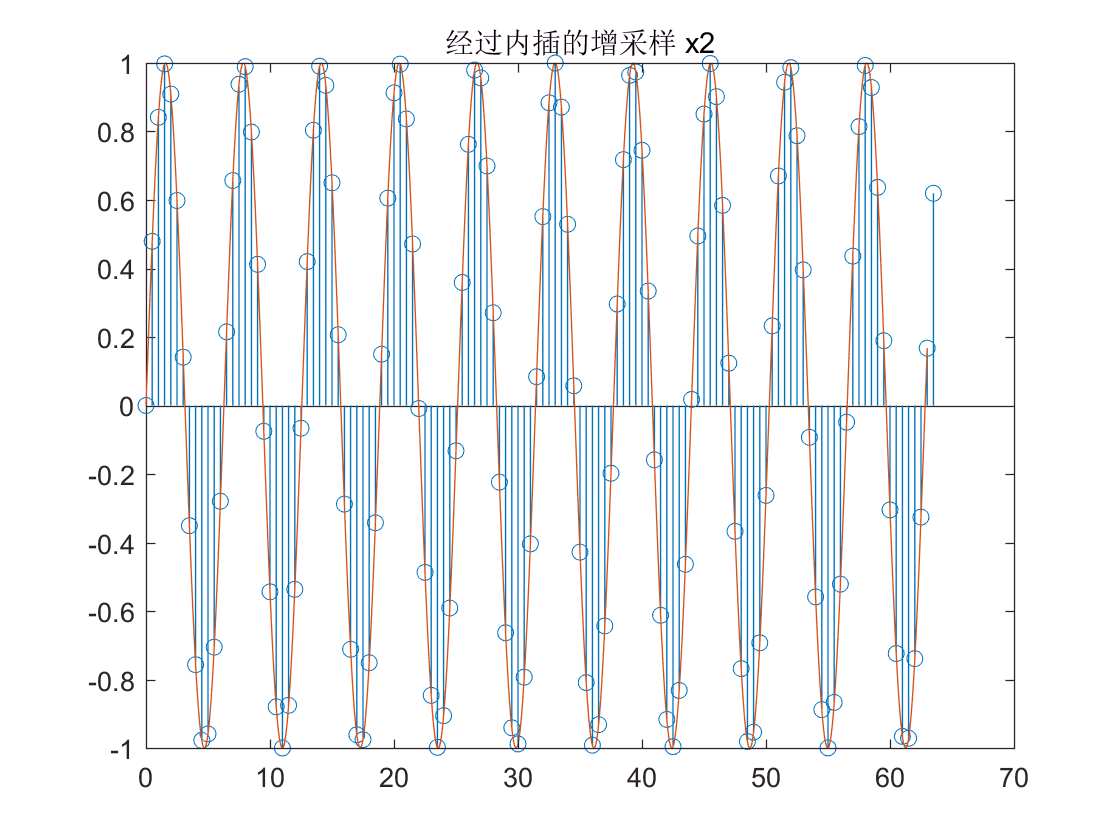

t2 = 0:127;
x2 = sin(t2/2);
stem(t2/2,x2)
title('经过内插的增采样 x2')
hold on
plot(tref,xref)
hold off

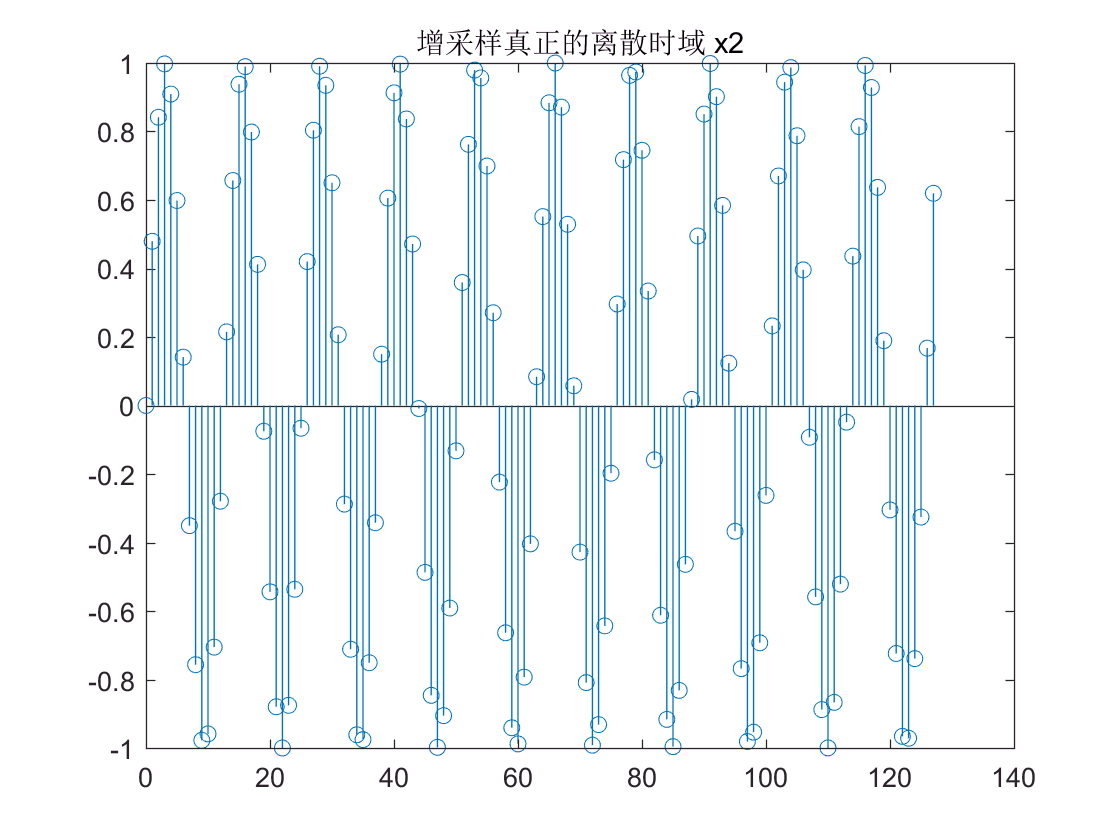


stem(t2,x2)
title('增采样真正的离散时域 x2')

## 假的增采样


$$\mathrm{x'}\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{c}
x\left\lbrack \frac{n}{2}\right\rbrack  & n=0,2,4,\ldotp \ldotp \ldotp ,2\left(N-1\right)\\
0 & n=1,3,5,\ldotp \ldotp \ldotp ,2N-1
\end{array}\right.$$


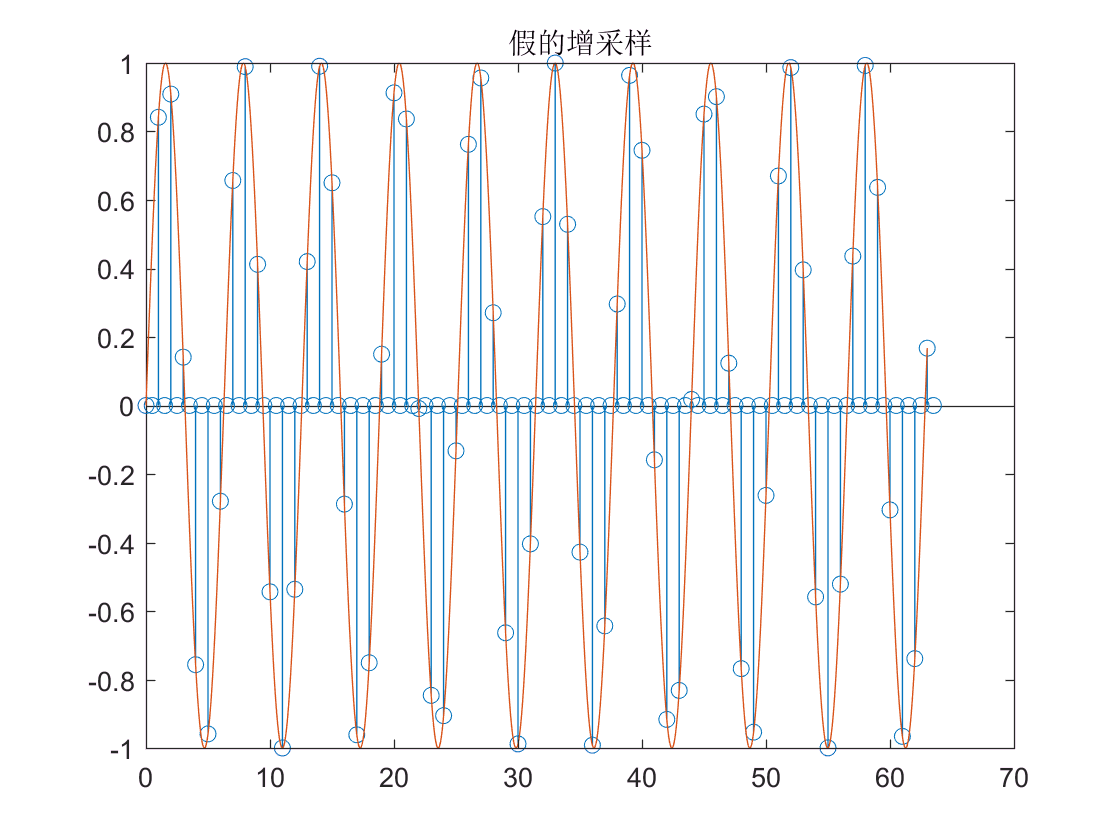


t3 = t2;
x3 = zeros(size(t3));
i = 0;
while i < 128
    x3(i+1) = xc(floor(i/2)+1);
    i= i+2;
end
stem(t3/2,x3)
title('假的增采样')
hold on
plot(tref,xref)
hold off

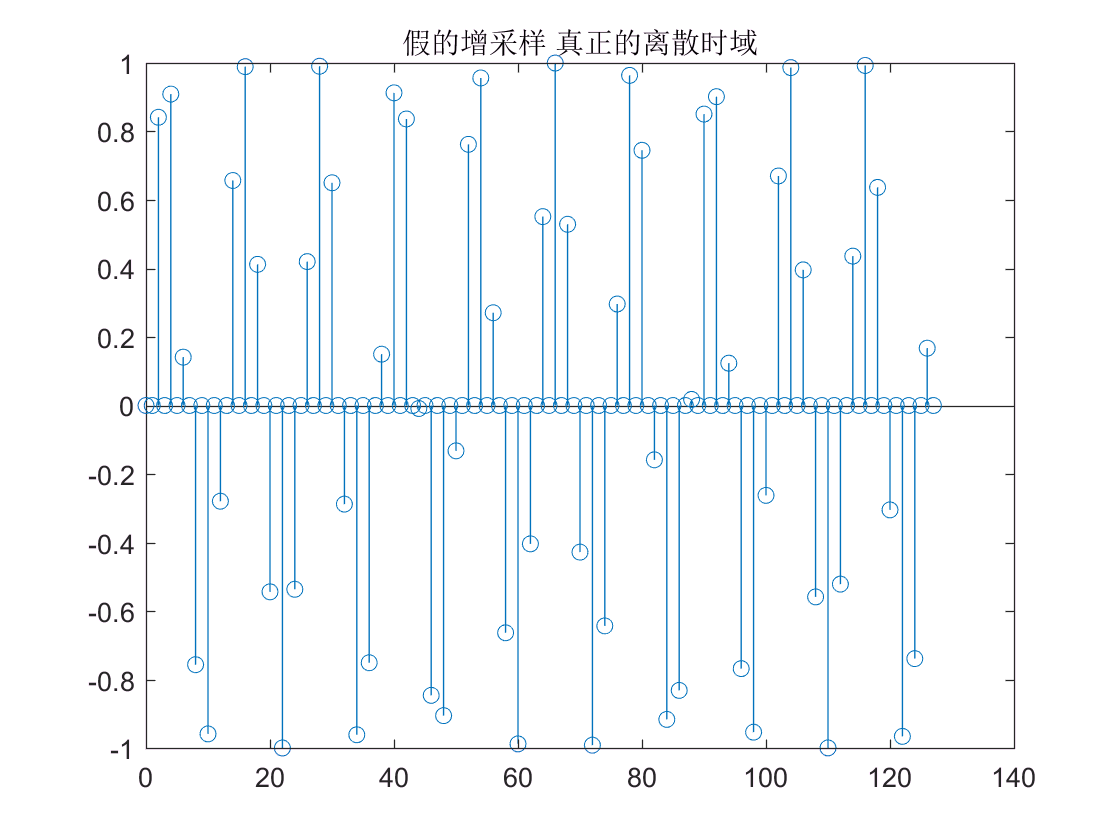


stem(t3,x3)
title('假的增采样 真正的离散时域')

# DFT

X = fft(xc)

X =    0.0966 + 0.0000i   0.1025 - 0.0991i   0.1209 - 0.2037i   0.1541 - 0.3205i   0.2070 - 0.4589i   0.2890 - 0.6348i   0.4188 - 0.8777i   0.6395 - 1.2541i   1.0739 - 1.9501i   2.2593 - 3.7793i  16.2985 -25.0517i  -4.1733 + 5.8877i  -2.0833 + 2.6964i  -1.4834 + 1.7607i  -1.2012 + 1.3069i  -1.0385 + 1.0351i  -0.9336 + 0.8514i  -0.8609 + 0.7172i  -0.8079 + 0.6135i  -0.7681 + 0.5300i  -0.7372 + 0.4605i  -0.7129 + 0.4010i  -0.6935 + 0.3490i  -0.6778 + 0.3027i  -0.6651 + 0.2608i  -0.6548 + 0.2222i  -0.6465 + 0.1863i  -0.6399 + 0.1525i  -0.6348 + 0.1202i  -0.6309 + 0.0892i  -0.6282 + 0.0590i  -0.6266 + 0.0294i  -0.6261 + 0.0000i  -0.6266 - 0.0294i  -0.6282 - 0.0590i  -0.6309 - 0.0892i  -0.6348 - 0.1202i  -0.6399 - 0.1525i  -0.6465 - 0.1863i  -0.6548 - 0.2222i  -0.6651 - 0.2608i  -0.6778 - 0.3027i  -0.6935 - 0.3490i  -0.7129 - 0.4010i  -0.7372 - 0.4605i  -0.7681 - 0.5300i  -0.8079 - 0.6135i  -0.8609 - 0.7172i  -0.9336 - 0.8514i  -1.0385 - 1.0351i  -1.2012 - 1.3069i  -1.4834 - 1.7607i  -2.083

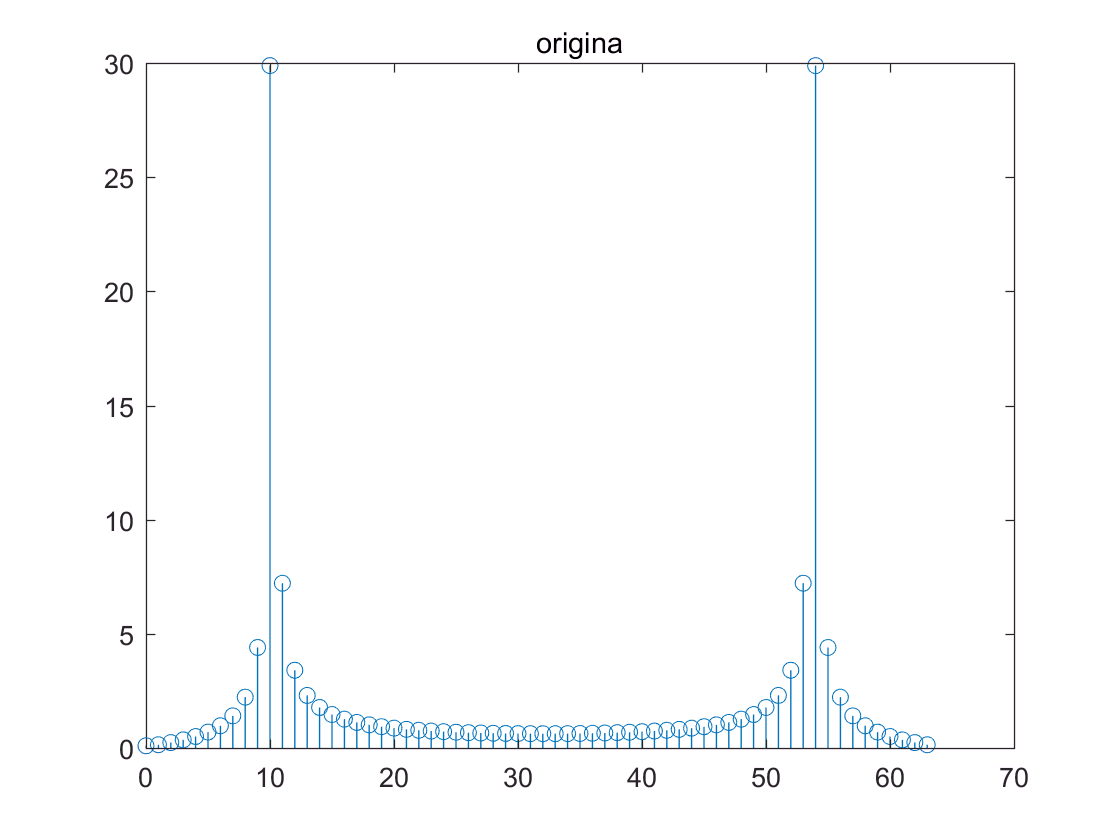

stem(t,abs(X))
title('origina')

# 降采样的DFT

回归DTFT，即


$$X_d(e^{j\omega})=\frac{1}{M}\sum_{r=1}^{M-1}X(e^{j\frac{\omega-2\pi r}{M}})$$


X1 = fft(x1)

X1 =   -0.2648 + 0.0000i  -0.2621 - 0.0642i  -0.2537 - 0.1314i  -0.2384 - 0.2048i  -0.2139 - 0.2896i  -0.1755 - 0.3936i  -0.1139 - 0.5320i  -0.0077 - 0.7381i   0.2044 - 1.1054i   0.7908 - 2.0410i   7.8025 -12.7003i  -2.4431 + 2.7433i  -1.4103 + 1.1179i  -1.1257 + 0.6154i  -1.0046 + 0.3467i  -0.9497 + 0.1589i  -0.9336 + 0.0000i  -0.9497 - 0.1589i  -1.0046 - 0.3467i  -1.1257 - 0.6154i  -1.4103 - 1.1179i  -2.4431 - 2.7433i   7.8025 +12.7003i   0.7908 + 2.0410i   0.2044 + 1.1054i  -0.0077 + 0.7381i  -0.1139 + 0.5320i  -0.1755 + 0.3936i  -0.2139 + 0.2896i  -0.2384 + 0.2048i  -0.2537 + 0.1314i  -0.2621 + 0.0642i


验证DFT的关系为$X_d \left\lbrack k\right\rbrack =\frac{1}{2}\left\lbrace X\left\lbrack k\right\rbrack +X\left\lbrack k-\frac{N}{2}\right\rbrack \right\rbrace ,k=0,1,\ldotp \ldotp \ldotp ,\left(\frac{N}{2}-1\right)$

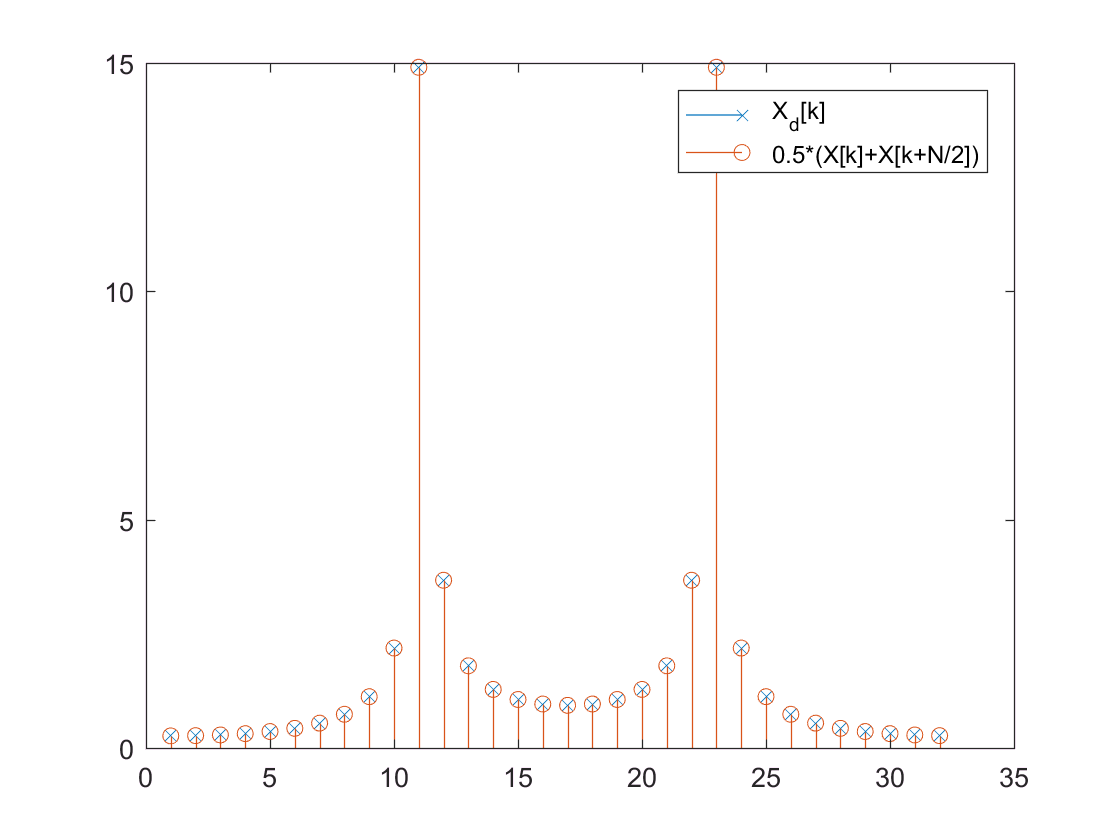

k = 0:31;
Xr = zeros(size(k));

Xr(k+1)=1/2*(X(k+1)+X(k+1+32));
stem(abs(Xr),'x')
hold on 
stem(abs(X1))
legend('X_d[k]','0.5*(X[k]+X[k+N/2])')
hold off

可见是一摸一样的。

# 增采样的DFT

## 真正的增采样(经过内插)

X2 = fft(x2)

X2 =    0.7308 + 0.0000i   0.7427 - 0.1862i   0.7796 - 0.3834i   0.8463 - 0.6049i   0.9525 - 0.8696i   1.1169 - 1.2090i   1.3770 - 1.6827i   1.8192 - 2.4229i   2.6888 - 3.8024i   5.0605 - 7.4481i  33.1398 -49.9801i  -7.8026 +11.9117i  -3.6214 + 5.5423i  -2.4201 + 3.6844i  -1.8541 + 2.7907i  -1.5270 + 2.2610i  -1.3151 + 1.9081i  -1.1676 + 1.6544i  -1.0595 + 1.4622i  -0.9772 + 1.3108i  -0.9127 + 1.1878i  -0.8611 + 1.0855i  -0.8189 + 0.9988i  -0.7839 + 0.9240i  -0.7546 + 0.8588i  -0.7296 + 0.8011i  -0.7082 + 0.7495i  -0.6897 + 0.7032i  -0.6736 + 0.6611i  -0.6595 + 0.6226i  -0.6470 + 0.5872i  -0.6360 + 0.5546i  -0.6261 + 0.5242i  -0.6173 + 0.4958i  -0.6094 + 0.4692i  -0.6023 + 0.4442i  -0.5959 + 0.4206i  -0.5901 + 0.3982i  -0.5848 + 0.3769i  -0.5800 + 0.3566i  -0.5757 + 0.3372i  -0.5717 + 0.3186i  -0.5681 + 0.3007i  -0.5648 + 0.2835i  -0.5617 + 0.2669i  -0.5590 + 0.2508i  -0.5564 + 0.2352i  -0.5541 + 0.2200i  -0.5520 + 0.2053i  -0.5501 + 0.1909i  -0.5483 + 0.1768i  -0.5467 + 0.1630i  -0.54

2*X

ans =    0.1932 + 0.0000i   0.2050 - 0.1982i   0.2417 - 0.4075i   0.3082 - 0.6410i   0.4141 - 0.9179i   0.5779 - 1.2695i   0.8375 - 1.7555i   1.2790 - 2.5081i   2.1478 - 3.9001i   4.5187 - 7.5585i  32.5969 -50.1033i  -8.3466 +11.7754i  -4.1667 + 5.3927i  -2.9668 + 3.5214i  -2.4024 + 2.6139i  -2.0770 + 2.0701i  -1.8672 + 1.7028i  -1.7217 + 1.4344i  -1.6159 + 1.2270i  -1.5361 + 1.0600i  -1.4745 + 0.9209i  -1.4258 + 0.8020i  -1.3870 + 0.6980i  -1.3557 + 0.6054i  -1.3303 + 0.5215i  -1.3097 + 0.4444i  -1.2931 + 0.3726i  -1.2798 + 0.3049i  -1.2695 + 0.2405i  -1.2618 + 0.1784i  -1.2565 + 0.1180i  -1.2533 + 0.0587i  -1.2523 + 0.0000i  -1.2533 - 0.0587i  -1.2565 - 0.1180i  -1.2618 - 0.1784i  -1.2695 - 0.2405i  -1.2798 - 0.3049i  -1.2931 - 0.3726i  -1.3097 - 0.4444i  -1.3303 - 0.5215i  -1.3557 - 0.6054i  -1.3870 - 0.6980i  -1.4258 - 0.8020i  -1.4745 - 0.9209i  -1.5361 - 1.0600i  -1.6159 - 1.2270i  -1.7217 - 1.4344i  -1.8672 - 1.7028i  -2.0770 - 2.0701i  -2.4024 - 2.6139i  -2.9668 - 3.5214i  -4.1

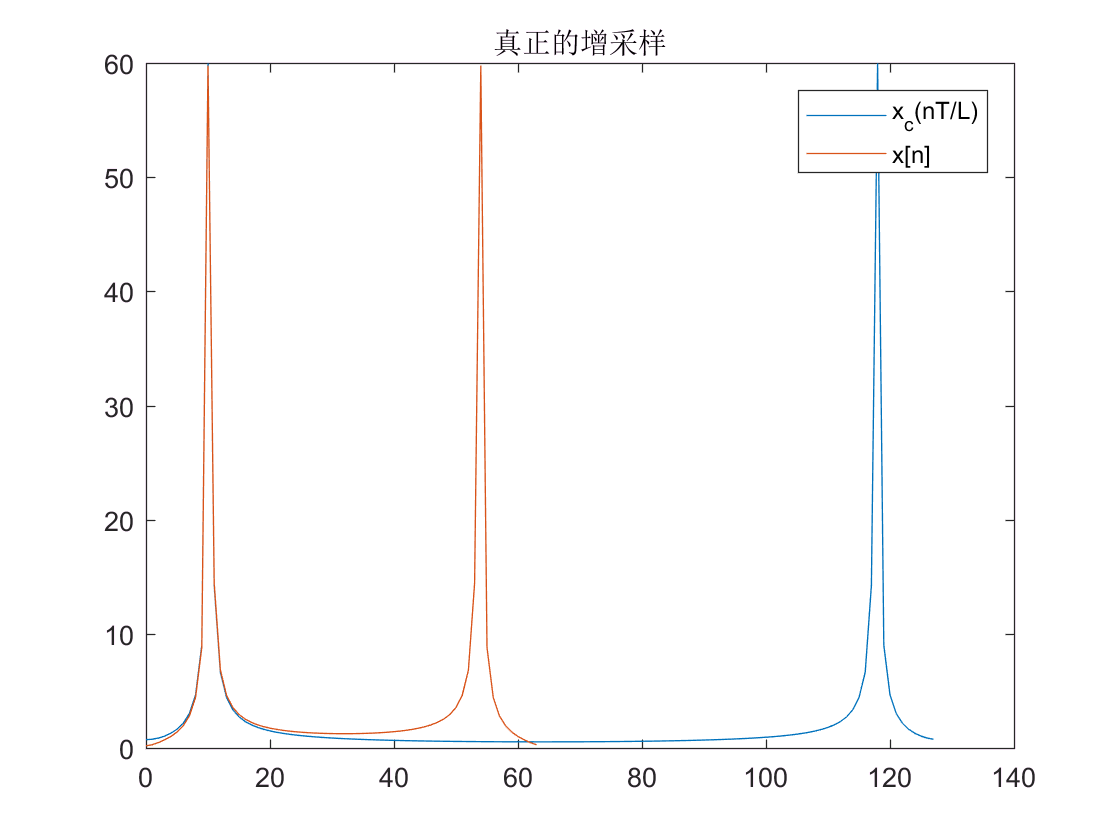


plot(t2,abs(X2))
hold on
plot(t,abs(2*X))
hold off
legend('x_c(nT/L)','x[n]')
title('真正的增采样')

## 假的增采样


$$x_e[n]=\begin{cases}
    x[n/L]&,n=L,2L,...\\
    0&,others
\end{cases}$$


X3 = fft(x3)

X3 =    0.0966 + 0.0000i   0.1025 - 0.0991i   0.1209 - 0.2037i   0.1541 - 0.3205i   0.2070 - 0.4589i   0.2890 - 0.6348i   0.4188 - 0.8777i   0.6395 - 1.2541i   1.0739 - 1.9501i   2.2593 - 3.7793i  16.2985 -25.0517i  -4.1733 + 5.8877i  -2.0833 + 2.6964i  -1.4834 + 1.7607i  -1.2012 + 1.3069i  -1.0385 + 1.0351i  -0.9336 + 0.8514i  -0.8609 + 0.7172i  -0.8079 + 0.6135i  -0.7681 + 0.5300i  -0.7372 + 0.4605i  -0.7129 + 0.4010i  -0.6935 + 0.3490i  -0.6778 + 0.3027i  -0.6651 + 0.2608i  -0.6548 + 0.2222i  -0.6465 + 0.1863i  -0.6399 + 0.1525i  -0.6348 + 0.1202i  -0.6309 + 0.0892i  -0.6282 + 0.0590i  -0.6266 + 0.0294i  -0.6261 + 0.0000i  -0.6266 - 0.0294i  -0.6282 - 0.0590i  -0.6309 - 0.0892i  -0.6348 - 0.1202i  -0.6399 - 0.1525i  -0.6465 - 0.1863i  -0.6548 - 0.2222i  -0.6651 - 0.2608i  -0.6778 - 0.3027i  -0.6935 - 0.3490i  -0.7129 - 0.4010i  -0.7372 - 0.4605i  -0.7681 - 0.5300i  -0.8079 - 0.6135i  -0.8609 - 0.7172i  -0.9336 - 0.8514i  -1.0385 - 1.0351i  -1.2012 - 1.3069i  -1.4834 - 1.7607i  -2.08

X

X =    0.0966 + 0.0000i   0.1025 - 0.0991i   0.1209 - 0.2037i   0.1541 - 0.3205i   0.2070 - 0.4589i   0.2890 - 0.6348i   0.4188 - 0.8777i   0.6395 - 1.2541i   1.0739 - 1.9501i   2.2593 - 3.7793i  16.2985 -25.0517i  -4.1733 + 5.8877i  -2.0833 + 2.6964i  -1.4834 + 1.7607i  -1.2012 + 1.3069i  -1.0385 + 1.0351i  -0.9336 + 0.8514i  -0.8609 + 0.7172i  -0.8079 + 0.6135i  -0.7681 + 0.5300i  -0.7372 + 0.4605i  -0.7129 + 0.4010i  -0.6935 + 0.3490i  -0.6778 + 0.3027i  -0.6651 + 0.2608i  -0.6548 + 0.2222i  -0.6465 + 0.1863i  -0.6399 + 0.1525i  -0.6348 + 0.1202i  -0.6309 + 0.0892i  -0.6282 + 0.0590i  -0.6266 + 0.0294i  -0.6261 + 0.0000i  -0.6266 - 0.0294i  -0.6282 - 0.0590i  -0.6309 - 0.0892i  -0.6348 - 0.1202i  -0.6399 - 0.1525i  -0.6465 - 0.1863i  -0.6548 - 0.2222i  -0.6651 - 0.2608i  -0.6778 - 0.3027i  -0.6935 - 0.3490i  -0.7129 - 0.4010i  -0.7372 - 0.4605i  -0.7681 - 0.5300i  -0.8079 - 0.6135i  -0.8609 - 0.7172i  -0.9336 - 0.8514i  -1.0385 - 1.0351i  -1.2012 - 1.3069i  -1.4834 - 1.7607i  -2.083

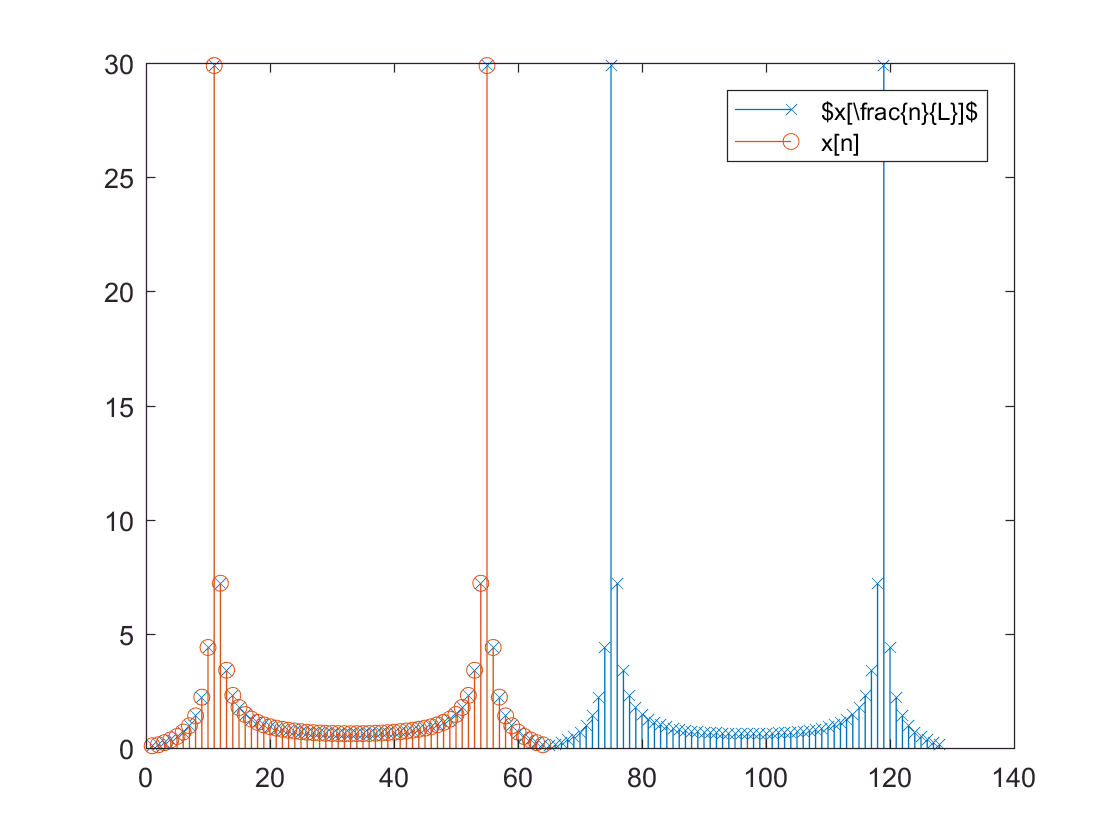


stem(abs(X3),'x')
hold on
stem(abs(X))
legend('$x[\frac{n}{L}]$','x[n]')
hold off

# 频域增减采样

## 减采样

## 增采样

-  没有做内插的增采样

从时域的角度反向推导

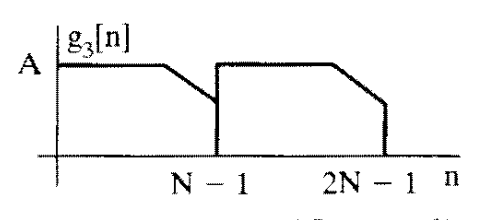

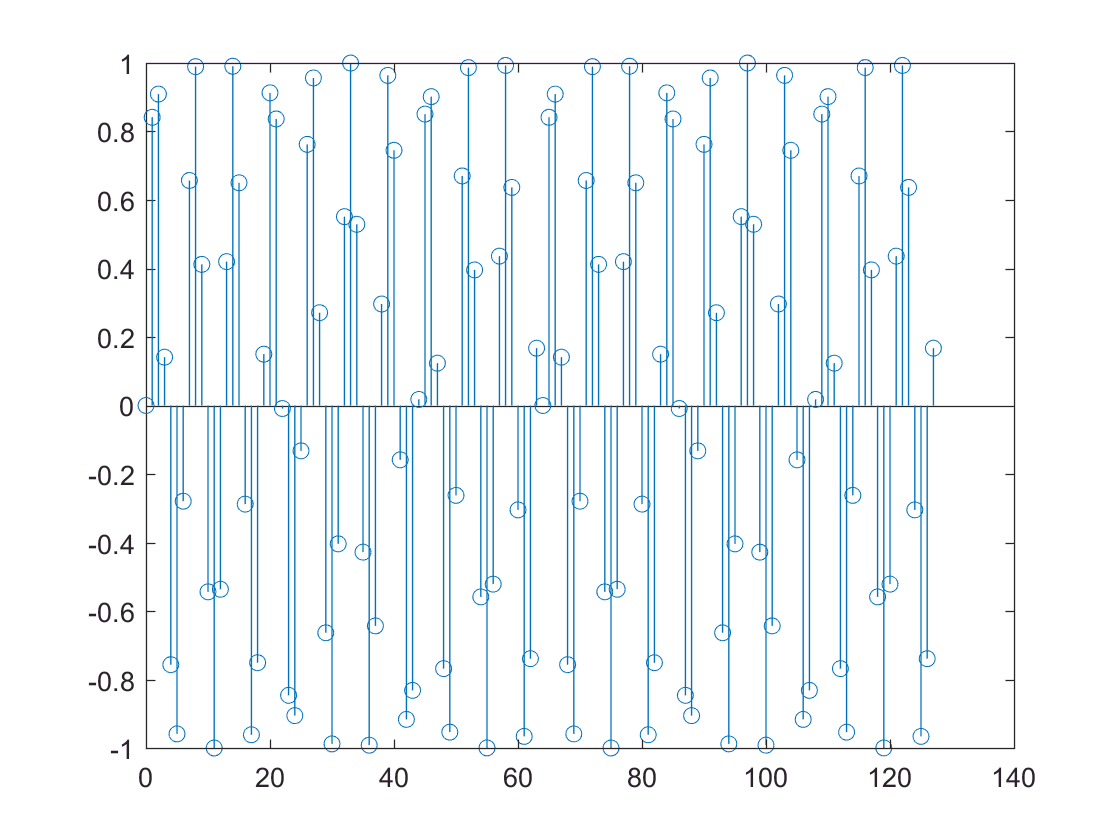

t4 = 0:127;
% 错误的，并不是x的周期延拓 x4 = sin(t4);
x4 = zeros(size(t4));
for i = 1:64
    x4(i) = xc(i);
end
for i = 65:128
    x4(i) = xc(i-64);
end
stem(t4,x4)

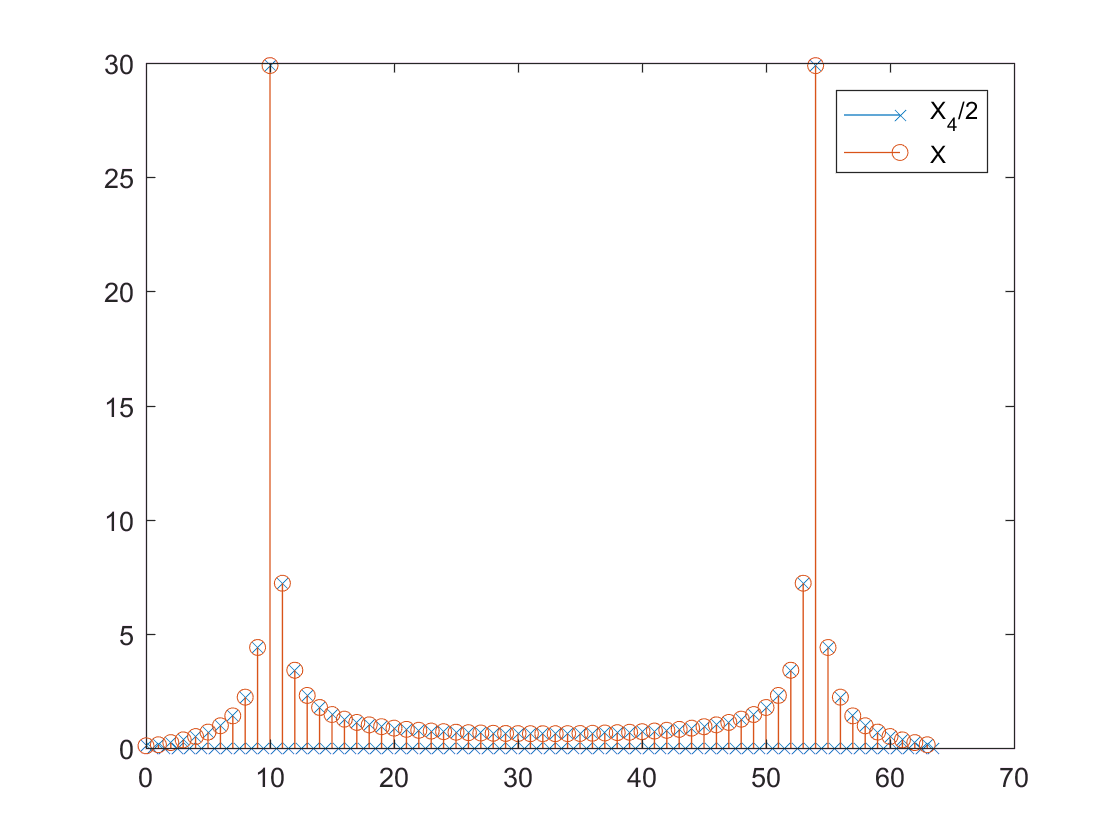

X4 = fft(x4);
stem(t4/2,abs(X4)/2,'x')
hold on 
stem(t,abs(X),'o')
legend('X4','X')
hold off

legend({'X_4/2','X'})

可见得到的结果却是为

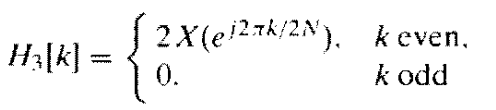

        2.  真的增采样对应时域补零（就像时域增采样对应频域补零）

仍然从时域得到结果（因为我们连续频域的表达式没有求）

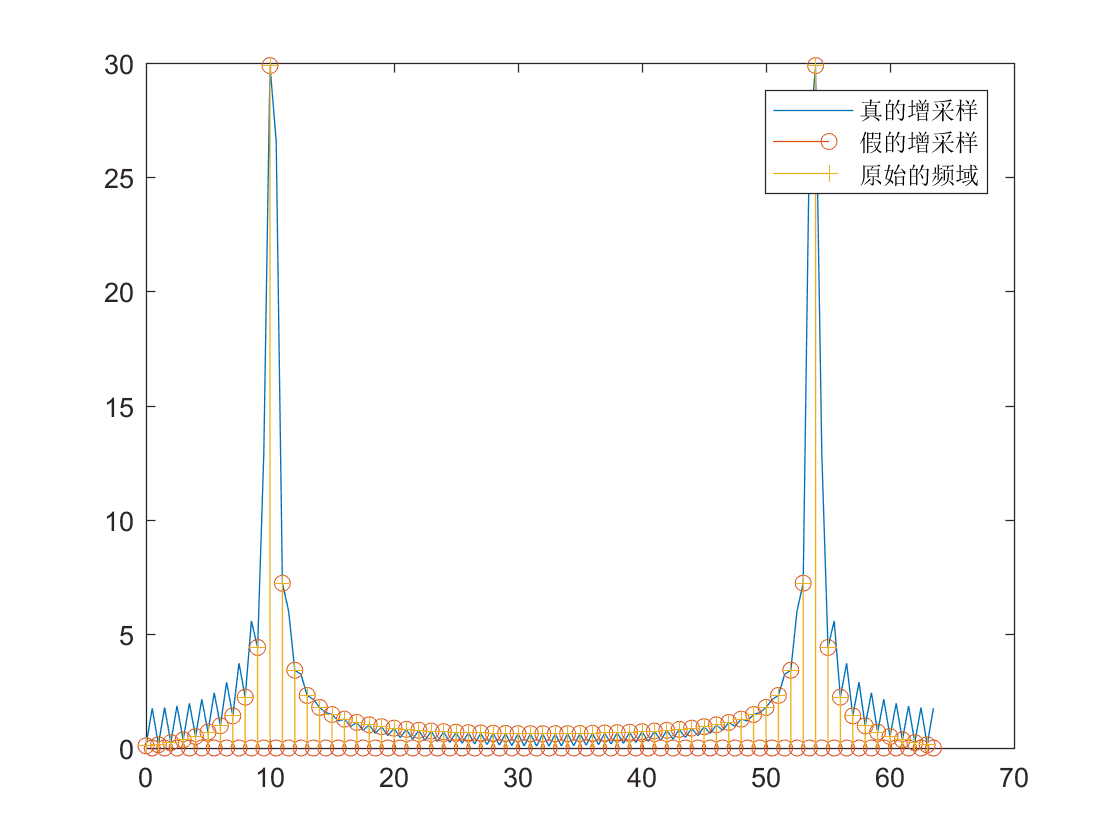

X5 = fft(xc, 2 * length(xc));  %fft(xc,127)
plot(t4/2, abs(X5))
hold on
stem(t4/2,abs(X4)/2);% 频域的这个真假增采样差了倍数？
stem(t,abs(X),'+')
legend('真的增采样','假的增采样','原始的频域')
hold off

确认一下反变换的时域是不是补零：

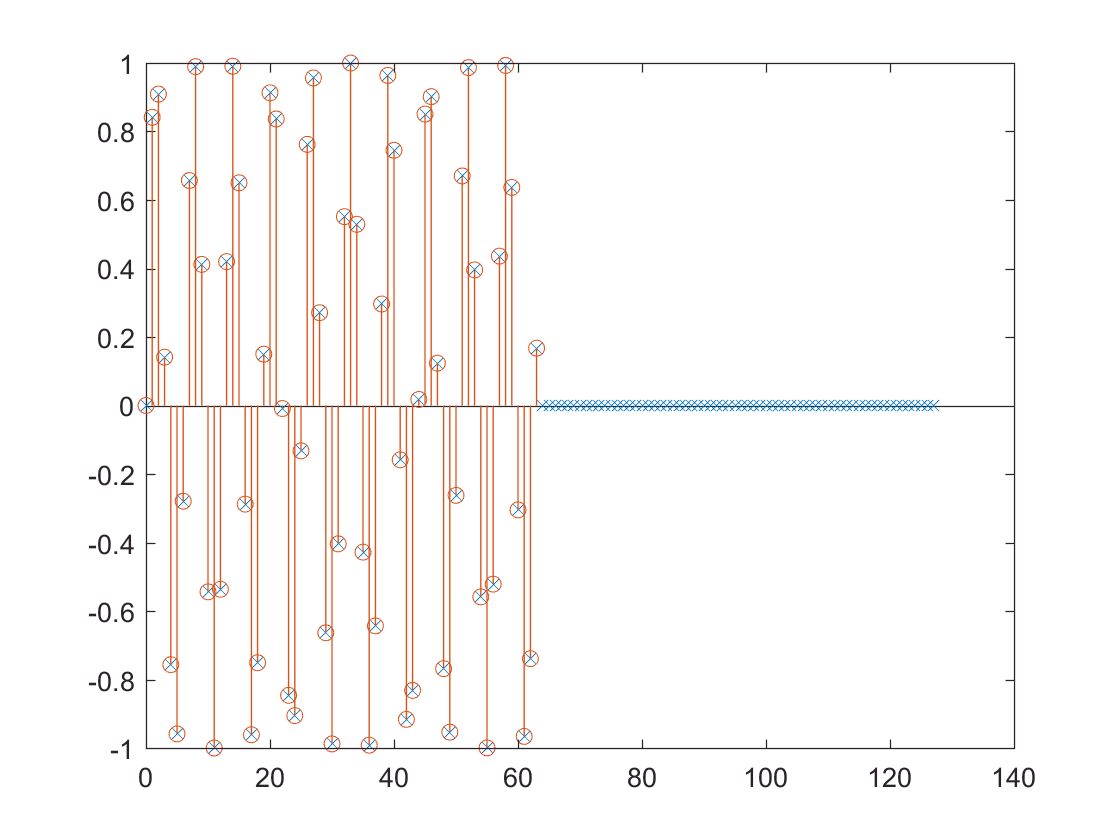

x5 = ifft(X5);
stem(t4,x5,'x');
hold on
stem(t,xc)
hold off

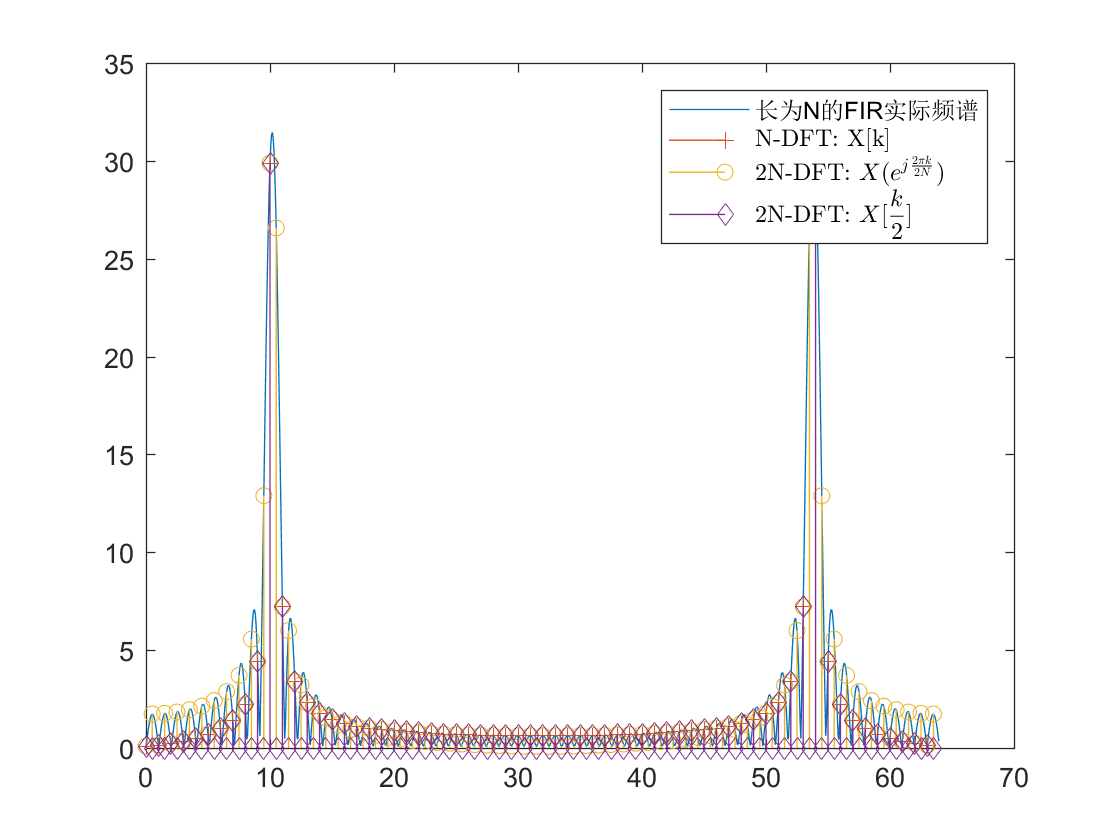

t6 = 0:1023;
X6 = fft(xc,1024);
plot(t6/16,abs(X6))
hold on
stem(t,abs(X),'+')
stem(t4/2, abs(X5))
stem(t4/2,abs(X4)/2,'d');% 频域的这个真假增采样差了倍数？
hold off
l = legend('长为N的FIR实际频谱','N-DFT: X[k]','2N-DFT: $$X(e^{j\frac{2\pi k}{2N}})$$','2N-DFT: $$X[\frac{k}{2}]$$');
set(l,'interpreter','latex')

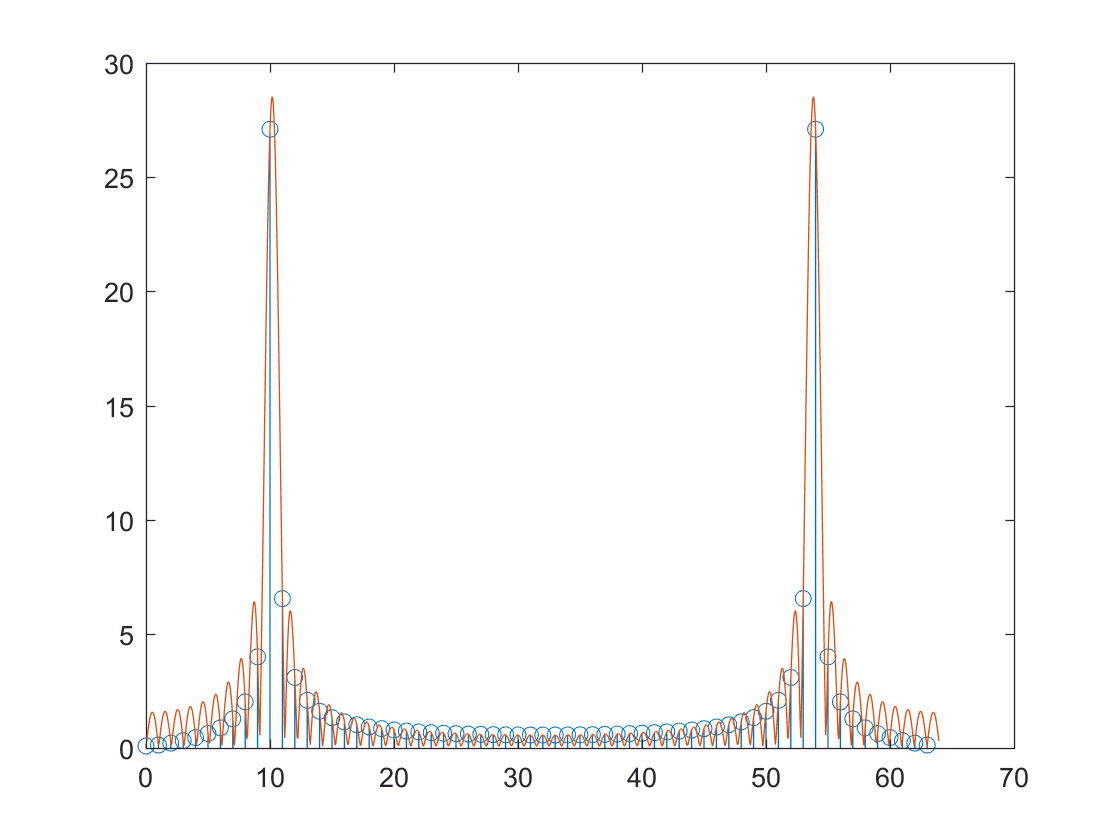

ximproved = sin(t)/(1-exp(-1i*64));
Ximproved = fft(ximproved);
Xim_c = fft(ximproved,1024);
stem(t,abs(Ximproved));
hold on
plot(t6/16,abs(Xim_c));
hold off

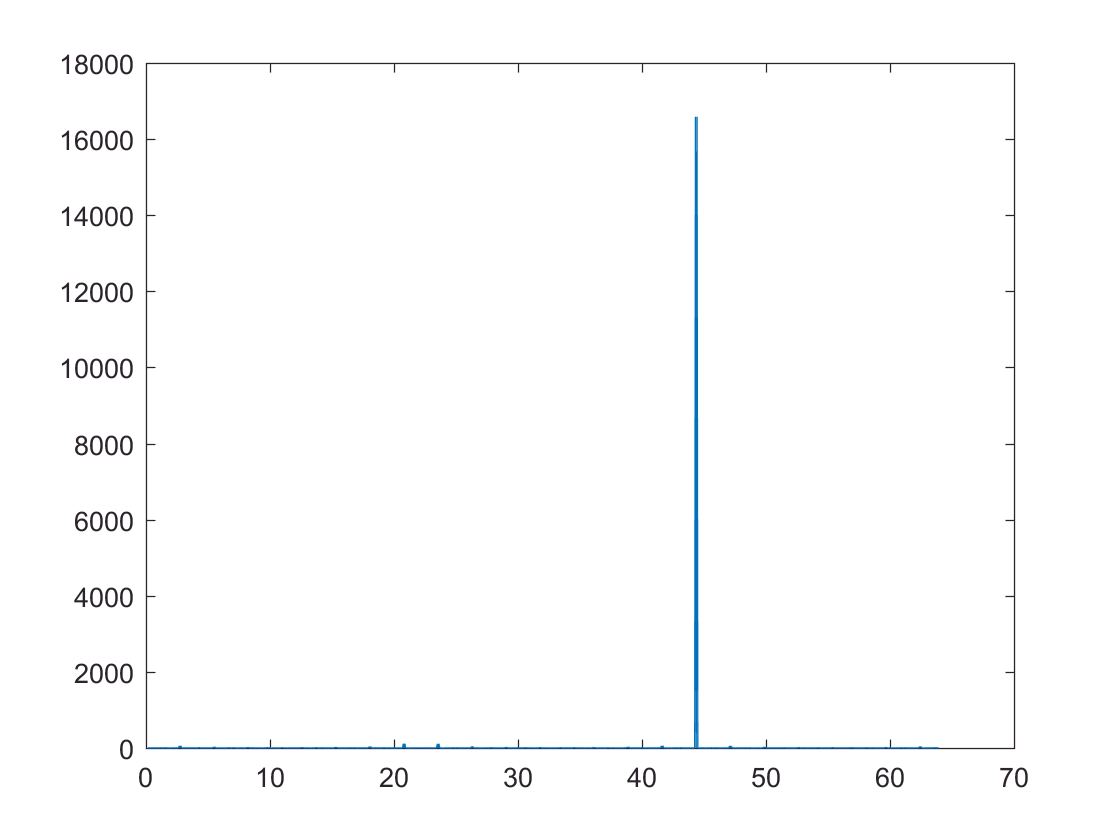

X111=exp(1i*(t6-1)/2)./(2*sin((t6-1)/2))-exp(1i*(t6+1)/2)./(2*sin((t6+1)/2));
plot(t6/16,abs(X111))